# **MATLAB Kursu**

*HAZIRLAYAN: BURAK ÖZPOYRAZ - burakozpoyraz@gmail.com*

## DERS - 2

### 1) MATRİSLER

Matrisler iki boyutlu vektörlerdir. Ancak MATLAB'de 2'den fazla boyutta da matrisler oluşturulabilir. Bir matris aşağıda verildiği gibi tanımlanabilir.

A1 = [1 2;
      3 4];
B = [-3 -7 4; 5 8 12];
C = [0 -4 9 7 16; -6 17 15 24 22; 2 -13 11 14 -21];

C_size = size(C);
C12 = C(1, 2);
C(2, 3) = 100;
C41 = C(4, 1);
C_sub = C(2 : 3, [1 3 5]);
C(4, 3) = -27; % What do you expect as the result?

İki matrisin birbirine eşit olup olmadığını kontrol etmek için normal eşitlik kontrol etme operatörü kullanılabilir. İki matrisin elemanları ayrı ayrı kontrol edilerek sonuçta yine bir matris elde edilir.

D = [1 2 3 4 5; 6 7 8 9 10];
E = [1 2 3 4 5; 7 8 9 10 11];
matrix_equality = D == E

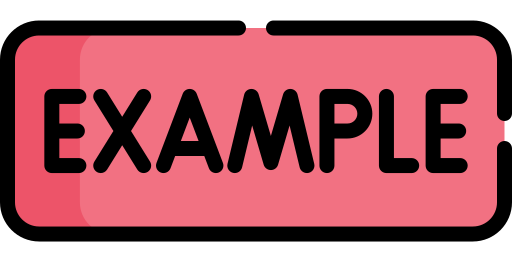

Aşağıda verilen M ve N matrislerinin birbirine eşit olup olmadığını kontol ederek sonuçta eşitlik durumunda "1", diğer durumda ise "0" elde ediniz. İpucu olarak aşağıdaki adımlar verilmiştir:

- Bir matristeki toplam eleman sayısını elde ediniz.

- Matrislerin eşitliklerini kontrol ettikten sonra kaç tane eşit eleman olduğunu sayınız.

- Eşit eleman sayısı toplam eleman sayısına eşit ise sonuç 1, değilse 0 olacaktır.

Ekstra olarak ***sum*** fonksiyonunun aşağıdaki özelliği verilmiştir:


$$\text{sum}\bigg(A = \pmatrix{1 & 3 & 4 \cr 5 & 7 & 9}\bigg) = \pmatrix{6 & 10 & 13}$$


M = [1 3 7; 5 6 9];
N = [1 3 7; 5 6 9];

Tamamen sıfırlardan veya birlerden oluşan matrisler ile birim matris aşağıda verildiği gibi oluşturulabilir.

Z23 = zeros(2, 3);
O37 = ones(3, 7);
I3 = eye(3);
I34 = eye(3, 4)

Matrislerin transpozu daha önce vektörler için anlatıldığı şekilde elde edilebilir.

F = [2 4 5; 6 8 10];
F_transpose = transpose(F);

Matrislerin aritmetik işlemleri aşağıda verildiği gibi yapılabilir.

M1 = [1 2 3; 4 5 6];
M2 = [-3 -7 8; -5 3 -11];
matrix_addition = M1 + M2;
matrix_subtraction = M1 - M2;
matrix_scalar_multiplication = M1 .* M2;
M1 = 3 * M1;

M3 = [-2 15 6 17; -1 0 4 3];
M4 = [5 7 13 16 34; -3 12 14 -16 -5; 1 -18 -26 -33 28; 9 -18 -13 36 21];
matrix_multiplication = M3 * M4;

M5 = [2 4 6; 8 10 12];
V1 = [3; 5; 7];
mat_vec_multiplication = M5 * V1;

inequality_check = (M5 > 9);

M6 = [3 5; 7 9];
M6_inv = inv(M6);
M6_inv2 = M6^(-1);

M6_square = M6.^2;

Rastgele (random) elemanlardan oluşan vektörler ve matrisler oluşturmak için bazı hazır fonksiyonlar kullanılabilir.

uni_vec = rand(1, 7); % Uniformly distributed vector in the range [0 1]
uni_mat = rand(3, 5);
uni_int_vec = randi([1, 4], [1, 5]); % Uniformly distributed integers 
% in the vector [1 4]
uni_int_mat = randi([1, 4], [5, 4]);
gauss_vec = randn(1, 1e5); % Gaussian distributed vector with zero mean and 
% unit variance
uni_comp_vec = randn(1, 1e5) + 1i * randn(1, 1e5); % Complex Gaussian 
% distributed vector with zero mean and variance 2

Aşağıda verilen [1 5] aralığında dengeli bir dağılım gösteren vektörde 3 elemanının sıklığını hesaplayınız.

vec = randi([1, 5], [1, 10]);

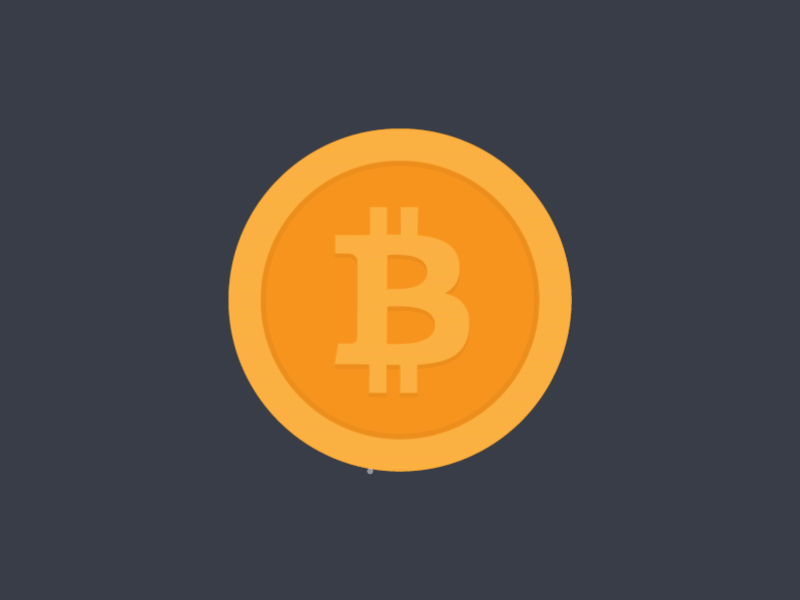

Bir madeni parayı 3 defa attığınızda en az bir yazı gelme olasılığını hesaplayan kodu yazınız.

 

### 2) PROBLEM / KÜLTÜR HESABI

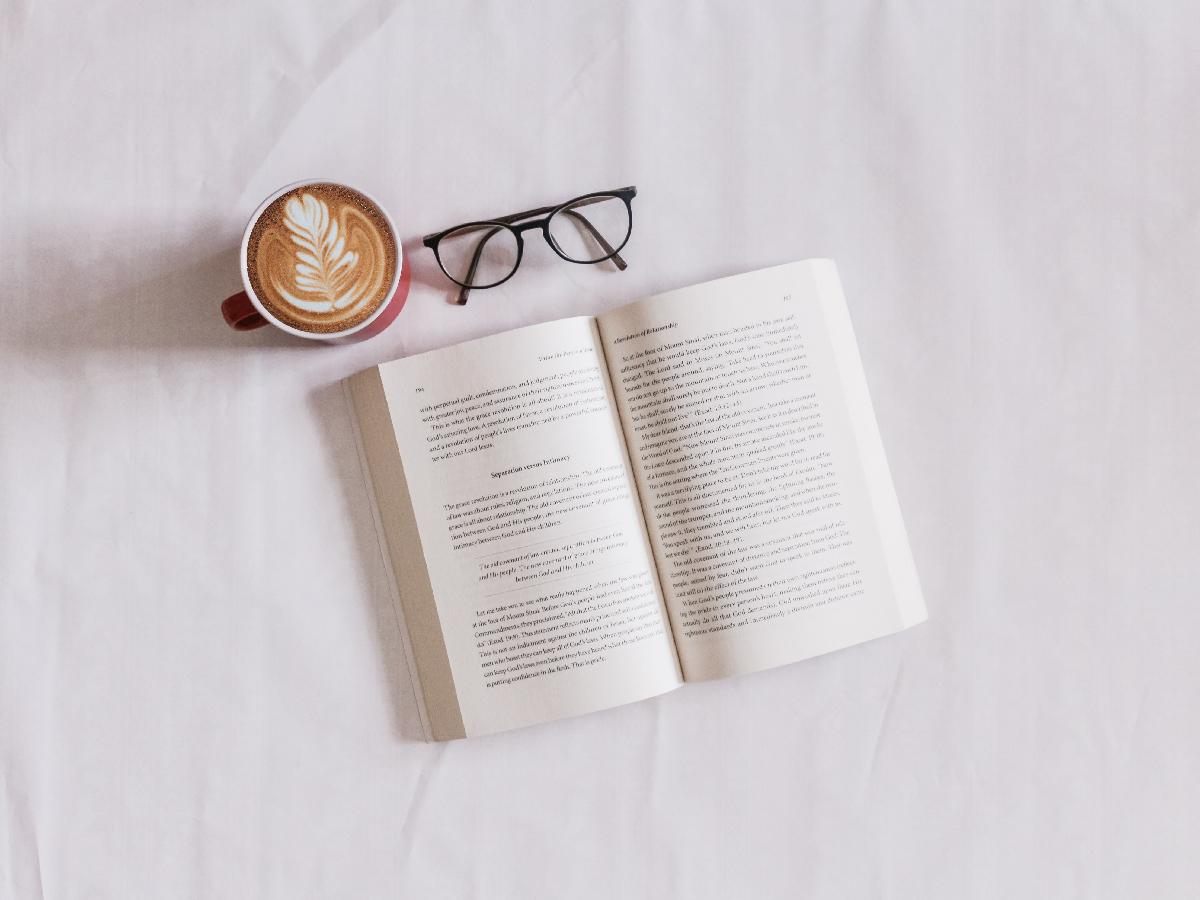

Kitap kurdu olan bir kişi elindeki kitapların hepsini bitirdikten sonra yeni bir kitap almaya karar vermiştir. Bunun için yeni alabileceği 10 adet kitap belirlemiştir. Ancak hesaplı bir kişi olduğu için internetten 3 farklı kitap satışı yapan sitede aynı kitapların fiyatlarını araştırmış ve sonucunda bir tablo yapmıştır. Tabloyu aşağıdaki gibi elde etmiştir:

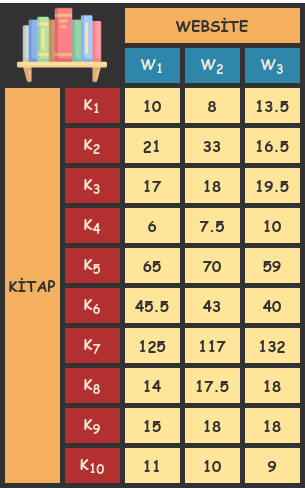

Sadece fiyatlara göre alışveriş yapmak istemeyen, kullanıcıların memnun kalıp kalmadığını da araştıran kitap kurdumuz, kullanıcıların yukarıdaki kitap alışverişlerini yaptıklarında ne kadar memnun kaldıklarına dair bir tablo oluşturmak istemektedir.

**1) **Kitap kurdumuzun memnuniyet tablosunu biz oluşturacağız. Puanlamanın 1'den 5'e kadar olduğu düşünülürse, 4 adet kullanıcının her bir websiteden aldığı her kitap için verdiği puanı içeren bir matrisi, rastgele olarak oluşturunuz.

*Hint: Burada 3 adet değişken (kullanıcılar, kitaplar ve siteler) olduğu için 3 boyutlu bir matris oluşturulmalıdır.*

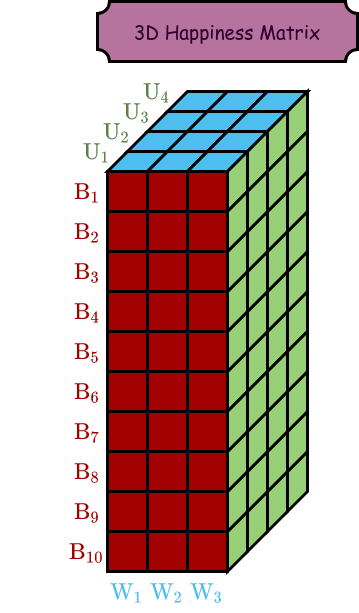

% Happiness Matrix////////////////////////////////////
% >>
% ////////////////////////////////////////////////////

**2) **Kitap kurdumuz, bu iki tabloyu (memnuniyet ve fiyat tabloları) kullanarak bazı istatistikler elde edip, hangi siteden hangi kitabı sipariş vereceğine karar verecektir. Bunun için öncelikle kitapların en düşük fiyattan satıldığı sitelerden oluşan bir vektör elde etmek ve sonrasında bu kitaplardan hangisinin ortalama en yüksek memnuniyet puanına sahip olduğunu tespit etmek istemiştir.

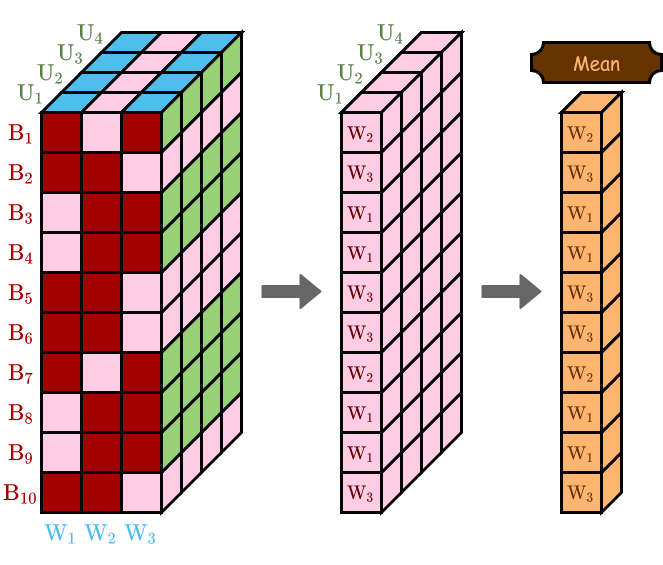

% Price Matrix////////////////////////////////////////
price_matrix = [10 8 13.5; 21 33 16.5; 17 18 19.5; 6 7.5 10; 65 70 59;
                45.5 43 40; 125 117 132; 14 17.5 18; 15 18 19.5; 11 10 9];
% ////////////////////////////////////////////////////

% Books With Minimum Price////////////////////////////
% We find the indices of the websites that each book
% is sold at minimum price.
% >>
% ////////////////////////////////////////////////////

% Happiness Matrix of Minimum Price Websites//////////
% We create the 2D happiness matrix (matrix at the
% middle with rose color) composed of happiness values
% from the minimum prices websites. (Hint: reshape, 
% repmat, and sub2ind functions)
% >>
% ////////////////////////////////////////////////////

% Mean Vector/////////////////////////////////////////
% >>
% ////////////////////////////////////////////////////

% Book Selection From Mean Vector/////////////////////
% >>
% ////////////////////////////////////////////////////

**3) **Kitap kurdumuz başka bir şekilde daha hesap yaparak en verimli seçeneği bulmak istemektedir. Bunun için şimdi de her bir kitabın her bir siteden satışı sonrası kullanıcıların memnuniyet puanlarının ortalamasını almak istemektedir.

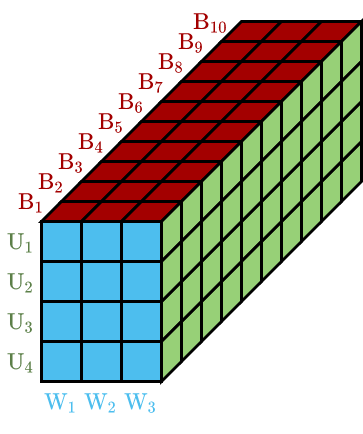

% Reshaped Happiness Matrix///////////////////////////
happiness_matrix_permute = permute(happiness_matrix, [3 2 1]);
% ////////////////////////////////////////////////////

% Average Happiness Scores////////////////////////////
% The figure below is obtained by the following code.
% >>
% ////////////////////////////////////////////////////

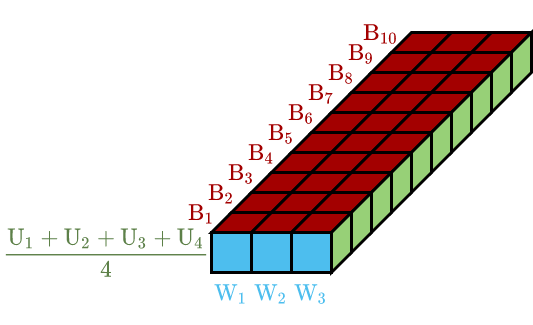

% Dimension Reduction/////////////////////////////////
% The figure below is obtained by the following code.
mean_happiness_matrix = squeeze(mean_happiness_matrix);
% ////////////////////////////////////////////////////

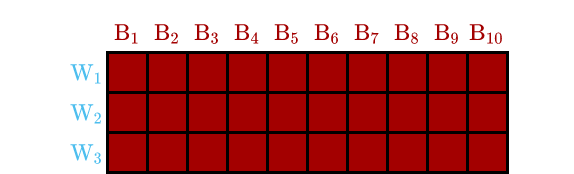

% Transpose///////////////////////////////////////////
% >>
% ////////////////////////////////////////////////////

**4) **Memnuniyet ortalamalarını bulduğuna göre elinde her kitabın her bir siteden satışına dair ortalama memnuniyet puanını içeren bir tablo ve bir de ücret bilgisini içeren ikinci bir tablo bulunmaktadır. Düşük ücretli ve maksimum ortalama memnuniyet puanına sahip seçeneği bulmak istediği için aşağıdaki gibi bir skor tanımlamıştır:


$$S = \frac{\text{Memnuniyet Puani }}{\text{Ücret}}$$


Buna göre her kitabın her bir siteden satışına dair skoru hesaplamak ve en yüksek skora ait seçeneği bulmak istemektedir.

% Score Matrix////////////////////////////////////////
% >>
% ////////////////////////////////////////////////////

% Book Selection From Score Matrix////////////////////
% >>
% ////////////////////////////////////////////////////